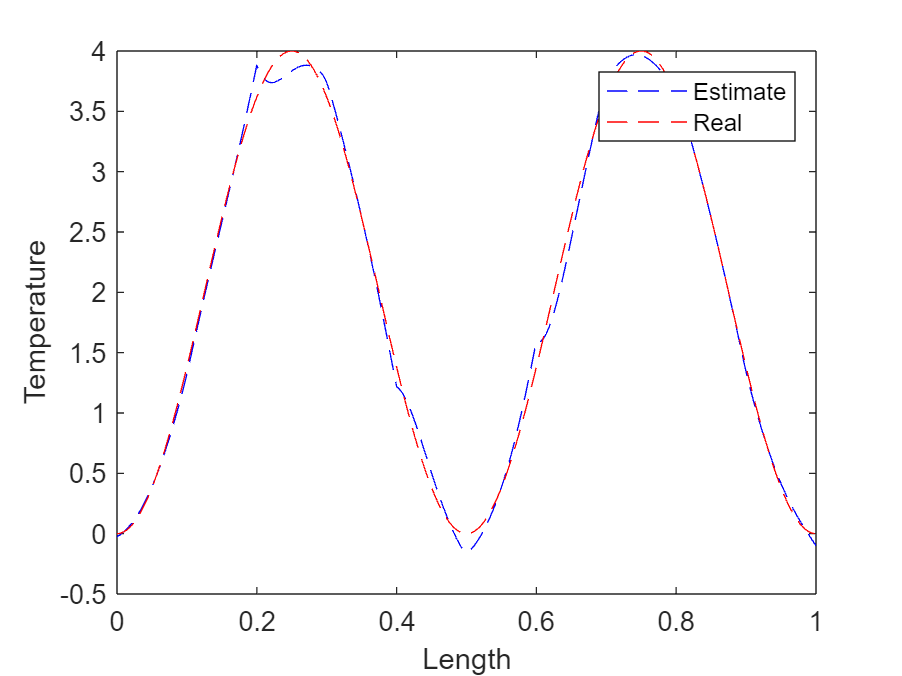

% N
n_1=100;
% N_s
n_s=5;


% Interval
h_1=1/n_s;
h_2=h_1/n_1;

% X-axis
x=zeros(n_s,n_1+1);
for i=0:n_s-1
    x_1=i*h_1:h_2:(i+1)*h_1;
    x(i+1,:)=x_1;
end

% u hat matrix
u_hat=zeros(n_1+1,1);
for j=1:n_1+1
    u_hat(j,1)=2*sin(4*pi*x(1,j)+3/2*pi)+2;
end
for i = 2:n_s
    u_tem=zeros(n_1+1,1);
    for j=1:n_1+1
        u_tem(j,1)=2*sin(4*pi*x(i,j)+3/2*pi)+2;
    end
    u_hat=cat(2,u_hat,u_tem);
end



% B^s matrix
B_1=zeros(n_1+1,n_1+1);
B_2=zeros(n_1+1,n_1+1);
B_3=zeros(n_1+1,n_1+1);
B_1(1,1)=1;
B_2(1,1)=1;
B_2(1,n_1+1)=-1;
B_3(1,n_1+1)=-1;

% M matrix
M=eye(n_1+1);
for i=1:n_1/2
    M(i,i)=500-1000/n_1*(i-1);
    M(n_1+1-i,n_1+1-i)=500-1000/n_1*(i-1);
end


% K matrix
K_1=zeros(n_1+1,n_1+1);
for i=1:n_1+1
    for j=1:n_1+1
        % overlapping condition 1
        if i==j
            if i==1
                K_1(i,j)=n_1-2;
            elseif i==n_1+1
                K_1(i,j)=n_1-2;
            else
                K_1(i,j)=n_1*2;
            end
        % overlapping condition 2
        elseif j-i==1
            if i==1
                K_1(i,j)=-n_1+1;
            else
                K_1(i,j)=-n_1;
            end
        elseif i-j==1
            if i==n_1+1
                K_1(i,j)=-n_1+1;
            else
                K_1(i,j)=-n_1;
            end
        end
    end
end

% u matrix
u = sym(sprintf('u_%d', 1), [n_1+1,1]);
for i=2:n_s
    u_1=sym(sprintf('u_%d', i), [n_1+1,1]);
    u=cat(2,u,u_1);
end

%u_2 = sym('u2', [n_1+1,1]);
%u_3 = sym('u3', [n_1+1,1]);

% f matrix
f=sym(sprintf('f_%d', 1),[n_1+1,1]);
for i=2:n_s
    f_1=sym(sprintf('f_%d', i),[n_1+1,1]);
    f=cat(2,f,f_1);
end
%f_2=sym('f2',[n_1+1,1])
%f_3=sym('f3',[n_1+1,1])

% lambda matrix
lambda=sym('l',[n_1+1,1]);

% mu matrix
mu=sym(sprintf('mu_%d', 1),[n_1+1,1]);
for i=2:n_s
    mu_1=sym(sprintf('mu_%d', i),[n_1+1,1]);
    mu=cat(2,mu,mu_1);
end
%mu_1=sym('mu1',[n_1+1,1]);
%mu_2=sym('mu2',[n_1+1,1]);
%mu_3=sym('mu3',[n_1+1,1]);

%gamma matrix
ga=sym(sprintf('ga_%d', 1),[1,n_1+1]);
for i=2:n_s-1
    ga_1=sym(sprintf('ga_%d', i),[1,n_1+1]);
    ga=cat(1,ga,ga_1);
end
%ga_1=sym('ga1',[n_1+1,1]);
%ga_2=sym('ga1',[n_1+1,1]);
%ga_3=sym('ga1',[n_1+1,1]);

% J equantion
J=1/2*(u(:,1)-u_hat(:,1))'*M*(u(:,1)-u_hat(:,1))+1/2*f(:,1)'*M*f(:,1)+1/2*(lambda'*M*lambda);
for i=2:n_s
    J=J+1/2*(u(:,i)-u_hat(:,i))'*M*(u(:,i)-u_hat(:,i))+1/2*(f(:,i)'*M*f(:,i));
end

% KU-f-lambdaB
exp_1=mu(:,1)'*(K_1*u(:,1)-f(:,1)-B_1'*lambda);
for i=2:n_s
    if i==n_s
        exp_1=exp_1+mu(:,i)'*(K_1*u(:,i)-f(:,i)-B_3'*lambda);
    else
        exp_1=exp_1+mu(:,i)'*(K_1*u(:,i)-f(:,i)-B_2'*lambda);
    end
end

% boundary condition
exp_2=ga(1,:)*(B_3*u(:,1)+B_1*u(:,2));
for i=2:n_s-1
    exp_2=exp_2+ga(i,:)*(B_3*u(:,i)+B_1*u(:,i+1));
end
% Lagrange
L = J+exp_1+exp_2;

% KKT
grad_u = gradient(L, u(:,1));
grad_f = gradient(L, f(:,1));
grad_lambda = gradient(L, lambda);
grad_mu = gradient(L, mu(:,1));
grad_ga = gradient(L, ga(1,:));

% Solving
%none=zeros(n_1+1,1)
eqns = [grad_u == 0; grad_f == 0; grad_lambda == 0; grad_mu==0; grad_ga==0];
for i=2:n_s
    if i~=n_s
        grad_u = gradient(L, u(:,i));
        grad_f = gradient(L, f(:,i));
        grad_mu = gradient(L, mu(:,i));
        grad_ga = gradient(L, ga(i,:));
        eqns=[eqns; grad_u == 0; grad_f == 0; grad_mu==0; grad_ga==0];
    else
        grad_u = gradient(L, u(:,i));
        grad_f = gradient(L, f(:,i));
        grad_mu = gradient(L, mu(:,i));
        eqns=[eqns; grad_u == 0; grad_f == 0; grad_mu==0];
    end
end
sol = vpasolve(eqns);

% Result
u_sol = double(subs(u, fieldnames(sol), struct2cell(sol)));
f_sol = double(subs(f, fieldnames(sol), struct2cell(sol)));
x_axis=0:1/(n_s*n_1):1;
u_plot_e=zeros(n_s*n_1+1,1);
cnt=1;
for i=1:n_s
    for j=1:n_1+1
        if i==1
            u_plot_e(cnt,1)=u_sol(j,i);
            cnt=cnt+1;
        else
            if j~=1   
                u_plot_e(cnt,1)=u_sol(j,i);
                cnt=cnt+1;
            end
        end
    end
end

u_plot_r=zeros(n_s*n_1+1,1);
cnt=1;
for i=1:n_s
    for j=1:n_1+1
        if i==1
            u_plot_r(cnt,1)=u_hat(j,i);
            cnt=cnt+1;
        else
            if j~=1   
                u_plot_r(cnt,1)=u_hat(j,i);
                cnt=cnt+1;
            end
        end
    end
end

% Temperature
figure;
plot( x_axis,u_plot_e, 'b--',x_axis,u_plot_r,'r--');
xlabel('Length'); ylabel('Temperature');
legend('Estimate','Real');